# **demo15 of Im2mesh package**

demo15 - Edit polygonal boundary before meshing

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 300; height = 300;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function bounds2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Convert Image to polyshape 

### Load Image

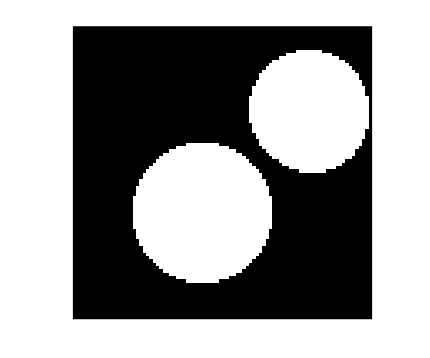

im_o = imread('Circle.tif');
if size(im_o,3) == 3;  im_o = rgb2gray( im_o ); end

% image segmentation
num_level = 2;
thresh = multithresh( im_o, num_level-1 );
seg_im = imquantize( im_o, thresh );
im = uint8( mat2gray(seg_im)*255 );

imshow( im,'InitialMagnification','fit' );

### Get boundries from image

We have demostrate how to do this in example3 of demo01.mlx

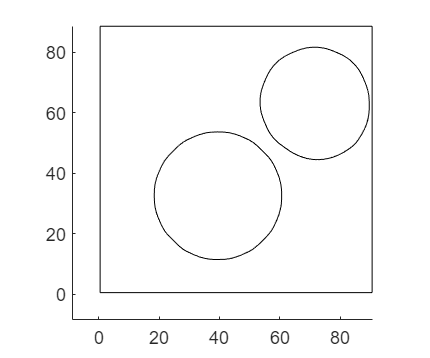

opt = [];   % reset opt
opt.tolerance = 0.05;
opt.tf_mesh = false;
bounds = im2mesh( im, opt );

% bounds is the simplified polygonal boundaries
plotBounds( bounds );

### Polyshape

It's tedious to edit boundaries directly. Using polyshape object will make things easier. We have demostrated polyshape in demo14. Please take a look at demo14 before you move to demo15.

Here, we use function bound2polyshape to convert a cell array of polygonal boundaries 'bounds' to a cell array of polyshape 'psCell'.

psCell = bound2polyshape(bounds);

Plot cell array of polyshape.

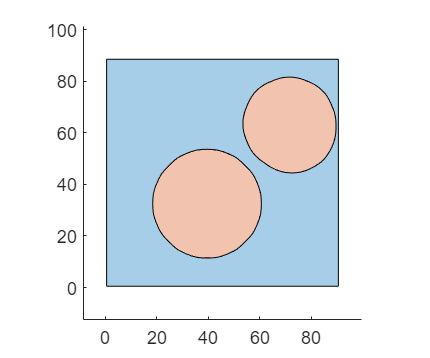

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

### Coordinates of 4 corners

Before we edit polyshape, we want to know about the x y coordinates of 4 corners in in variable psCell.

First, let's get the image size. This is for comparison.

size(im)

ans =     88    90


So the height and width of the input image is 88 and 90, respectively. The bottom left corner in the image is [0, 0]. The upper right corner in the image is [90, 88].

We use function xyRange to get the range of x y coordinates in boundary or polyshape.

[xmin,xmax,ymin,ymax] = xyRange( psCell )

xmin = 0.5000

xmax = 90.5000

ymin = 0.5000

ymax = 88.5000

So we can know the location of bottom left corner and upper right corner in the polygonal boundary.

xyBottomLeft = [ xmin, ymin ]

xyBottomLeft =     0.5000    0.5000


xyUpRight = [ xmax, ymax ]

xyUpRight =    90.5000   88.5000


Compared this with the size of the image, we notice a 0.5 shifting in x y coordinates. I forgot why there is 0.5 shifting in x y coordinates since some code in Im2mesh were written by me many years ago. Probably I want to be consistent with MATLAB built-in function bwboundaries.

Let's plot.

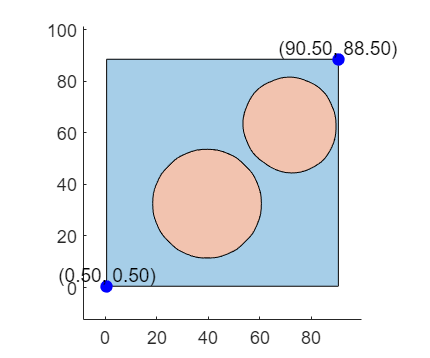

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end

xy = xyBottomLeft;
plot( xy(1), xy(2), 'bo', 'MarkerFaceColor', 'b');
text( xy(1), xy(2), sprintf('(%.2f, %.2f)', xy(1), xy(2)), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center' );

xy = xyUpRight;
plot( xy(1), xy(2), 'bo', 'MarkerFaceColor', 'b');
text( xy(1), xy(2), sprintf('(%.2f, %.2f)', xy(1), xy(2)), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center' );

hold off

Therefore, based on 4 corners, we can know the mid point of the upper boundary and the mid point of the right boundary. We will use them later.

% mid point of the upper boundary
xMidUp = (xmin+xmax)/2;
yMidUp = ymax;

% mid point of the right boundary
xMidRight = xmax;
yMidRight = (ymin+ymax)/2;

## Add a block

### Create a block

Let's create a block near the left side of psCell.

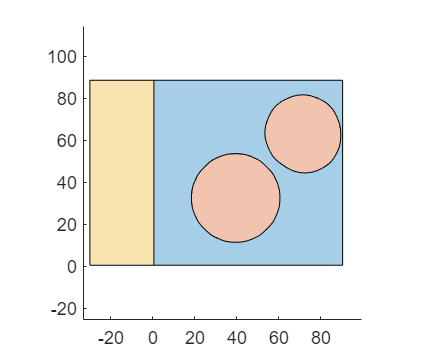

% define a block
vertex = [ -30, 0.5; 0.5, 0.5; 0.5, 88.5; -30, 88.5 ];
psBlock = polyshape(vertex);

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end

plot(psBlock)
hold off

### Append to the end of psCell

% append to the end of psCell
psCell{end+1} = psBlock;

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

### Merge geometry

We have assumed the block is a new phase in the geometry.

What if the block and the background are in the same phase? We can merge the block into the background.

First, we plot them one by one so we would know which is which.

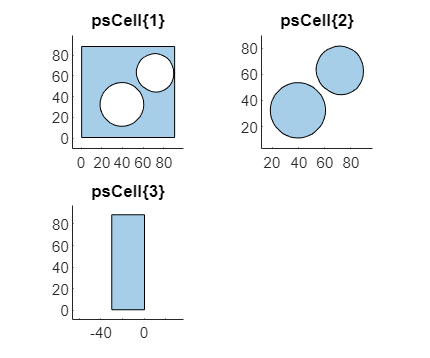

figure
for i = 1: length(psCell)
    subplot(2,2,i);
    plot( psCell{i} );  axis equal;
    title(['psCell\{' num2str(i), '\}']);
end

We saw that psCell{1} is the background. psCell{3} is the block.

We merge the block into the background.

psCell{1} = union( psCell{1}, psCell{3} );
psCell{3} = [];     % delete the block

length( psCell )

ans = 3

The length of psCell is 3 although the 3-th element is []. 

To avoid error in the following steps, we need to manually delete empty elements in the cell array.

% delete empty elements in cell array
psCell = psCell( ~cellfun('isempty', psCell) );
length( psCell )

ans = 2

Plot

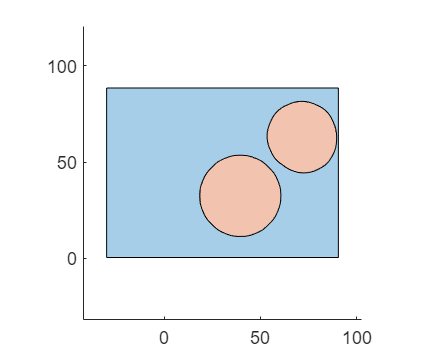

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

## Create interfacial transition zone

We can assume the circles are particles. 

We can use Matlab built-in function polybuffer to create interfacial transition zone (ITZ) around particles. ITZ may be useful in the FEA of composite materials.

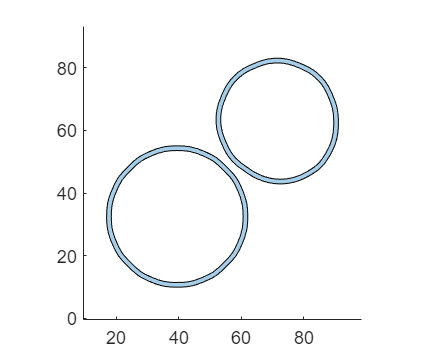

psParticle = psCell{2};
thickness = 1.5;  % unit: pixel
psITZ = polybuffer( psParticle, thickness, 'JointType', 'miter','MiterLimit', 20 );

psITZ = subtract( psITZ, psParticle );

plot(psITZ); axis equal

### Boolean operation

We use boolean operations to remove overlapped regions between psITZ and psCell.

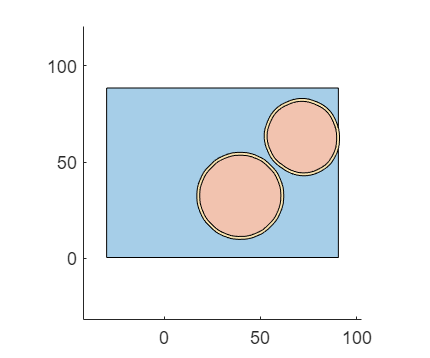

for i = 1: length(psCell)
    psCell{i} = subtract( psCell{i}, psITZ );
end

% add to the end of psCell
psCell{end+1} = psITZ;

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

## Add a notch

Let's add a oval-shape notch to the point [xMidUp, yMidUp].

Define a oval. The center of the oval is [xMidUp, yMidUp].

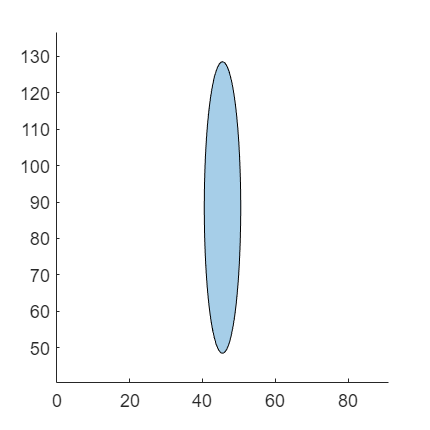

t = 0.05:0.03:2*pi;
x1 = xMidUp + 5*cos(t);
y1 = yMidUp + 40*sin(t);
psNotch = polyshape(x1,y1);

plot( psNotch ); axis equal

Add a oval-shape notch (by boolean operation - subtract).

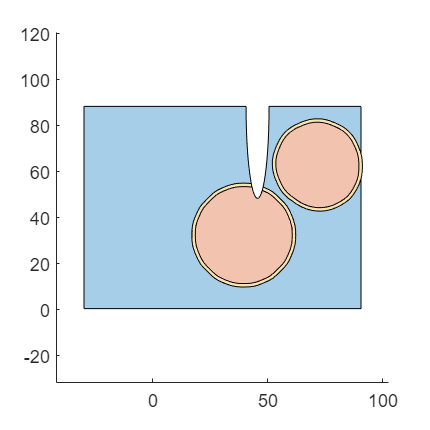

for i = 1: length(psCell)
    psCell{i} = subtract( psCell{i}, psNotch );
end

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

## Add a small square

Let's add a small square to the mid point of the right boundary. The mid point is [xMidRight, yMidRight].

We define a square. The center of the square is [xMidRight, yMidRight]. 

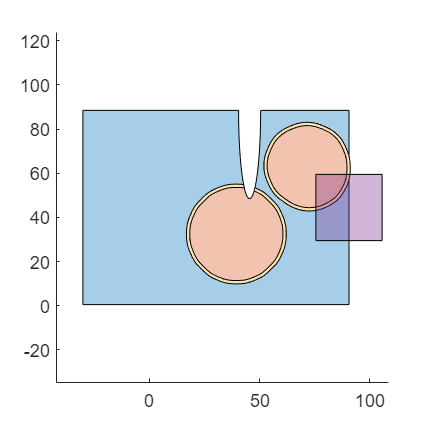

% define a square
vertex = [ 0 0; 1 0; 1 1; 0 1 ];
psUnitSq = polyshape(vertex);   % unit square
% set length and width
psSq = scale( psUnitSq, [30, 30]);

% set the centroid to [xMidRight, yMidRight]
[xc,yc] = centroid(psSq);
vec = [ xMidRight - xc, yMidRight - yc];
psSq = translate( psSq, vec );

% plot together
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
plot( psSq );
hold off

We saw that they are overlapped.

### Boolean operation

We use boolean operations to remove overlapped regions.

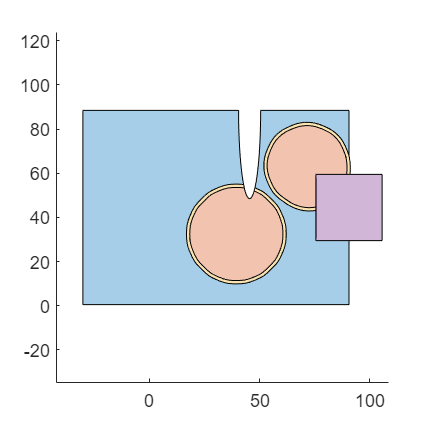

for i = 1: length(psCell)
    psCell{i} = subtract( psCell{i}, psSq );
end

% add to the end of psCell
psCell{end+1} = psSq;

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

## Before mesh generation

### Add intersect points

Polyshape objects are not able to find intersect points automatically. Therefore, we convert the cell array of polyshape to a cell array of polygonal boundaries, and use function addIntersectPnts to add intersect points to boundaries. 

Note that if we don't add intersect points, mesh generation will fail.

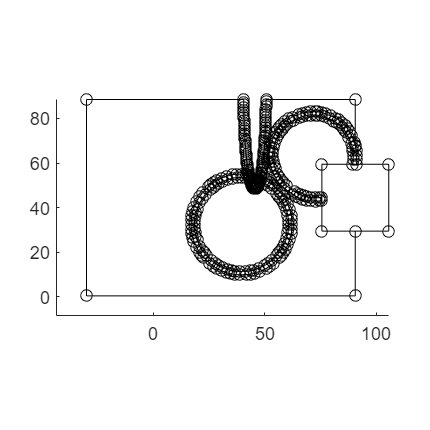

boundsNew = polyshape2bound(psCell);
tol_intersect = 1e-6;   % distance tolerance for intersect
boundsNew = addIntersectPnts( boundsNew, tol_intersect );

% show all vertices
plotBounds( boundsNew, false, 'ko-' );  

Zoom in

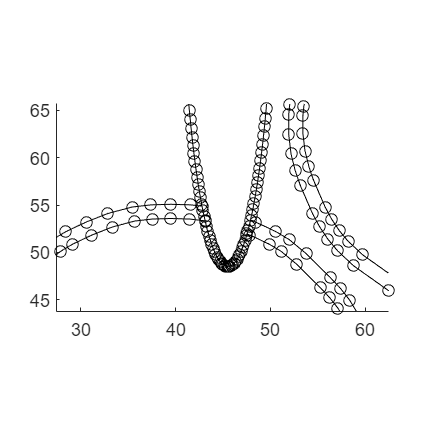

plotBounds( boundsNew, false, 'ko-' )
xlim([27.4 62.5])
ylim([43.8 65.7])

We notice there are a lot of vertices on the notch.

### Simplify boundaries

We want to reduce the number of vertices on the notch and on the boundary.

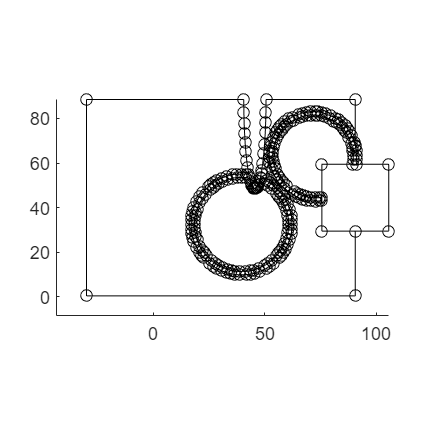

boundsNewCtrlP = getCtrlPnts( boundsNew );

% simplify
tolerance = 0.02;  % for Douglas-Peucker polyline simplification
boundsNewSimplified = simplifyBounds( boundsNewCtrlP, tolerance );

% show all vertices
plotBounds( boundsNewSimplified, false, 'ko-' );    

Zoom in

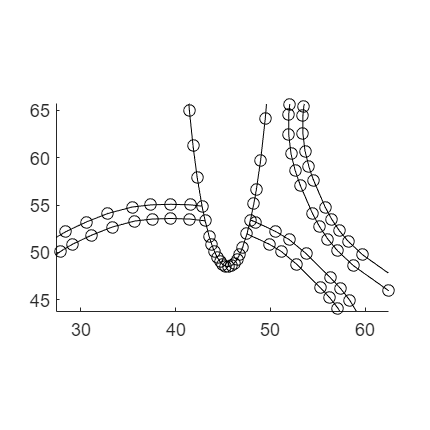

plotBounds( boundsNewSimplified, false, 'ko-' );
xlim([27.4 62.5])
ylim([43.8 65.7])

Wonderful! We saw that the number of vertices on the notch reduced a lot.

Note that you need to adjust the value of tolerance to achieve your desired reduction.

## Generate mesh

To generate mesh, we use function bounds2mesh.

Note that function bounds2mesh uses [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda) as mesh generator.

hmax = 500; 
grad_limit = 0.25;

[vert,tria,tnum] = bounds2mesh( boundsNewSimplified, hmax, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          7                294                493
         10                320                605
         19                333                964


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          9                434                493
         10                434                728
         20                488               2859
         22                489               2874


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
         10                 80               2842



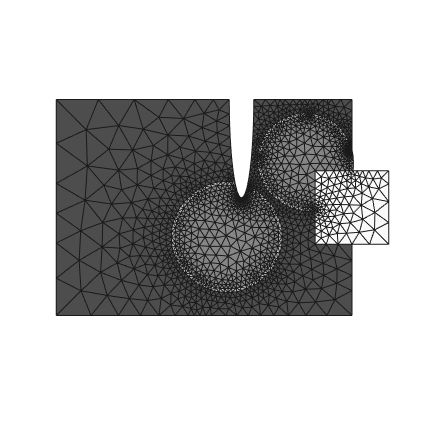

plotMeshes(vert,tria,tnum);

Zoom in

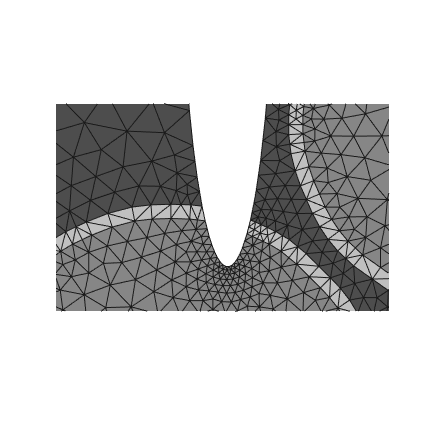

plotMeshes(vert,tria,tnum);
xlim([27.4 62.5])
ylim([43.8 65.7])

Wonderful!

We can also use open-source software Gmsh to generate mesh. 

We saw that the mesh density in some region is low. It's possible to refine mesh locally. Please refer to demo17 and demo16.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo